Nonlinear System Behavior: Second-Order System Response

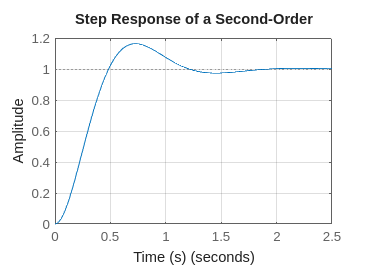

% Define the parameters
wn = 5;             % Natural frequency (radians)
zeta = 0.5;         % Damping ratio

% Define the numerator and transfer function
num = wn^2;
den = [1, 2*zeta*wn, wn^2];

% Create the transfer function
sys = tf(num, den);

% Simulate the step response
figure;
step(sys);
title('Step Response of a Second-Order');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

Nonlinear System Behavior: Pendulum with Friction

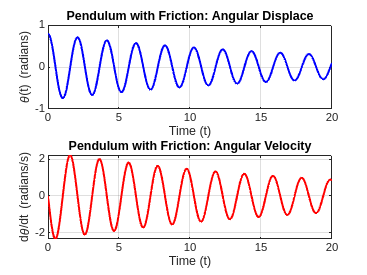

% Define the parameters
g = 9.81;           % Acceleration due to gravity(m/s^2)
L = 1;              % Length of the pendulum(m)
b = 0.1;            % Damping coefficient(friction)
m = 1;              % Mass of the pendulum bob(kg)
tspan = [0, 20];     % Time span for simulation
theta0 = [pi/4; 0]; % Initial conditions[theta(0)]

% Define the system of ODEs
pendulum = @(t, theta)[theta(2); -(b/m)*theta(2)-(g/L)*sin(theta(1))];
%pendulum = @(t, theta)[theta(2); -(b/m)*theta(2) - (g/L)*sin(theta(1))];

% Solve the ODE using ode45
[t, theta] = ode45(pendulum, tspan, theta0);

% Plot the results
figure;
subplot(211);
plot(t, theta(:, 1), 'b', 'LineWidth', 1.5);
title('Pendulum with Friction: Angular Displace');
xlabel('Time (t)');
ylabel('\theta(t) (radians)');
grid on;
subplot(212);
plot(t, theta(:, 2), 'r', 'LineWidth',1.5);
title('Pendulum with Friction: Angular Velocity');
xlabel('Time (t)');
ylabel('d\theta/dt (radians/s)');
grid on;

Nonlinear Systems and Equilibrium Points

% Finding Equilibrium Points of a Nonlinear System
syms x y

% Define the system of equations
eq1 = x - y^2 == 0;         % dx/dt = 0
eq2 = x^2 - y == 0;         % dy/dt = 0

% Solve the system of equations
equilibrium_points = solve([eq1, eq2], [x, y]);

% Display the equilibrium points
disp('Equilibrium Point:');

Equilibrium Point:


disp(equilibrium_points.x);

$$\left(\begin{array}{c} 0\\ 1\\ -\frac{1}{2}+\frac{\sqrt{3}\,\mathrm{i}}{2}\\ -\frac{1}{2}-\frac{\sqrt{3}\,\mathrm{i}}{2} \end{array}\right)$$

disp(equilibrium_points.y);

$$\left(\begin{array}{c} 0\\ 1\\ -\frac{1}{2}-\frac{\sqrt{3}\,\mathrm{i}}{2}\\ -\frac{1}{2}+\frac{\sqrt{3}\,\mathrm{i}}{2} \end{array}\right)$$

Multiple Equilibrium Points

% Define symbolic variables
syms x1 x2 u
% Define nonlinear system dynamics
f1 = x2;
f2 = -x1 - x2^3 + u;
f = [f1, f2];

% Equilibrium point
x1_e = 0;
x2_e = 0;
u_e = 0;

% Compute Jocobian matrices
A = jacobian(f, [x1, x2]);
B = jacobian(f, u);

% Evaluate Jacobians at the equilibrium point
A = double(subs(A, {x1, x2, u}, {x1_e, x2_e, u_e}));
B = double(subs(B, {x1, x2, u}, {x1_e, x2_e, u_e}));

% Display results
disp('Linearized A matrix:');

Linearized A matrix:


disp(A);

     0     1
    -1     0



disp('Linearized B matrix:');

Linearized B matrix:


disp(B);

     0
     1

